# Datos faltantes

Ya que hemos revisado formas para organizar y combinar nuestros datos, revisaremos uno de los problemas principales en el manejo de información, los datos faltantes

La mejor manera de lidiar con datos faltantes es comprender los datos disponibles y entender como están representados los faltantes

Los datos faltantes pueden deberse a una variedad de factores: error de escritura o lectura de la información, datos dañados o registro incompleto de los mismos, entre otros problemas

Es importante comprender porqué hay datos faltantes en un dataset, ya que un dataset incompleto puede generar un sesgo en un algoritmo de inteligencia artificial. Además identificar y y entender estos valores faltantes ayuda a su manejo correcto. comencemos con la clasificación de datos faltantes:

- MAR Missing At Random

- MCAR Missing Completely At Random

- MNAR Missing Not At Random

### Missing At Random (MAR)

Significa que la razón por la que hay faltantes no está relacionada con su valor subyacente, sino que está condicionado por otras variables

Por ejemplo, un dataset con información de presión sanguínea por edad, en el cual es probable  que a menor edad existan menos registros de pacientes en el que se toma esta información. La razón de los faltantes no es la presión sanguínea y su registro directamente, si no que está relacionado a otra variable, en este ejemplo, la edad.

### Missing Completely At Random (MCAR)

Significa que los datos faltantes no estan relacionados a alguna otra variable, por ejemplo un dataset obtenido a partir de cuestionarios o encuestas, en las que hay faltantes porque las personas no responden algunas preguntas por omisiones de manera aleatoria

### Missing Not At Random (MNAR)

Significa que la razón del dato faltante está relacionada con un valor de la misma

Por ejemplo una encuesta donde se pregunte el ingreso de las personas, en estos casos hay una  alta probabilidad que personas con altos salarios decidan no revelar esta información. Este tipo de faltantes son los mas difíciles de solventar debido a que pueden agregar sesgo a un modelo con relativa facilidad

### Manejo de datos faltantes

De manera general se tiene la opción "omitnan" para descartar datos numéricos faltantes al momento de realizar operaciones aritméticas o estadísticas.

Hay 2 opciones restantes, remover o reemplazar

#### Remover datos faltantes

Es la opción más sencilla, sin embargo para el caso de faltantes tipo MNAR no es recomendable ya que esto puede significar un sesgo importante en los resultados finales. En el caso de MAR, solo la remoción también puede generar sesgo, pero en caso de que el porcentaje de faltantes sea bajo, pueden descartarse con afectaciones menores hacia un modelo predictivo.

Para identificar y remover las filas con datos faltantes utilizaremos la función `rmmissing`. Los datos faltantes están etiquetados de acuerdo al tipo de dato (NaN, missing, unassigned, NaT).

### Reemplazar datos faltantes

La función a utilizar será `fillmissing` y alguna de sus opciones. Por ejemplo reemplazar un dato faltante por un valor constante. Entre los métodos mas comunes estan:

- Reemplazo por valor constante

- valor previo

- valor siguiente

- vecino mas cercano

- Interpolación lineal

- interpolación cúbica

- interpolación Lanczos

- media y mediana movil

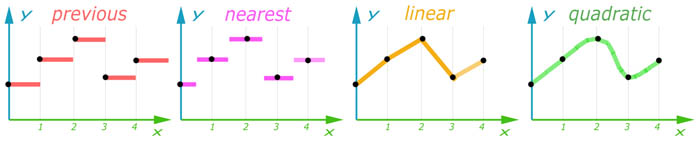

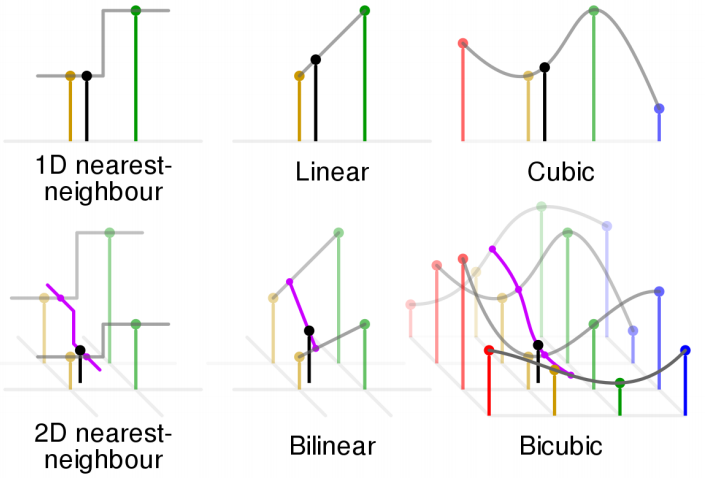

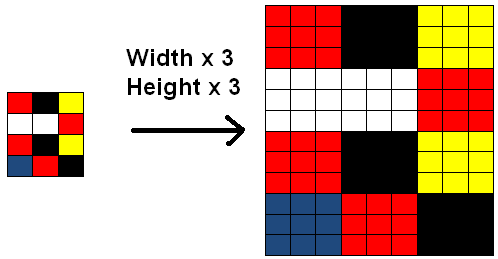

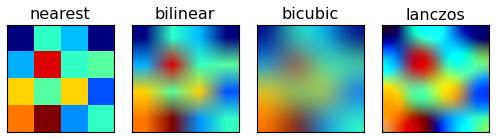

Es importante destacar que los métodos basados en ecuaciones de segundo grado o mayor (quadratic, cubic, spline, Makima) pueden entregar valor por encima del valor máximo o por debajo del mínimo en un conjunto de datos, y en el caso de datos faltantes al inicio o final de una serie, pueden marcar una tendencia que dispare los valores a valores fuera de rango

load patients
T = table(LastName,Gender,Smoker,Height,Weight,Age);
T.LastName = string(T.LastName);
T.LastName(3)=missing;
T = sortrows(T,'Height')

T = 100×6 table
     LastName        Gender      Smoker    Height    Weight    Age
    ___________    __________    ______    ______    ______    ___

    "Peterson"     {'Female'}    false       60       136      32 
    "Lewis"        {'Female'}    false       62       137      41 
    "Evans"        {'Female'}    false       62       121      39 
    "Sanchez"      {'Female'}    true        62       136      44 
    "Allen"        {'Female'}    false       63       143      39 
    "Young"        {'Female'}    false       63       114      25 
    "Carter"       {'Female'}    false       63       128      38 
    "Cook"         {'Female'}    false       63       124      38 
    "Rivera"       {'Female'}    false       63       130      29 
    "Powell"       {'Female'}    false    

T.Height(40:50)=nan;
T.Height(end-10:end)=nan;
% Para ubicar datos faltantes
faltantes=ismissing(T);
T

T = 100×6 table
     LastName        Gender      Smoker    Height    Weight    Age
    ___________    __________    ______    ______    ______    ___

    "Peterson"     {'Female'}    false       60       136      32 
    "Lewis"        {'Female'}    false       62       137      41 
    "Evans"        {'Female'}    false       62       121      39 
    "Sanchez"      {'Female'}    true        62       136      44 
    "Allen"        {'Female'}    false       63       143      39 
    "Young"        {'Female'}    false       63       114      25 
    "Carter"       {'Female'}    false       63       128      38 
    "Cook"         {'Female'}    false       63       124      38 
    "Rivera"       {'Female'}    false       63       130      29 
    "Powell"       {'Female'}    false    

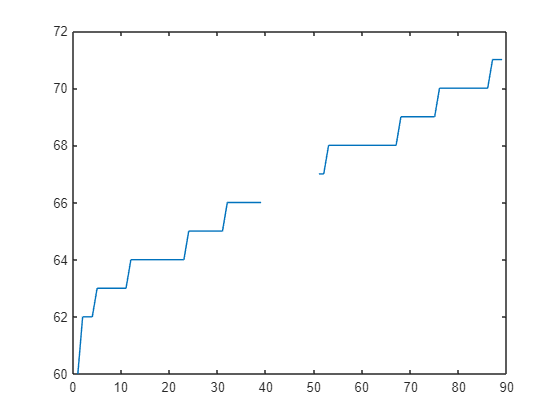


x=1:100;
plot(x,T.Height)

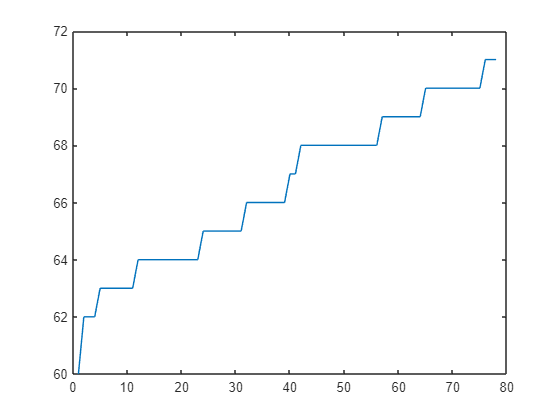

datosT = rmmissing(T.Height);
plot(datosT)

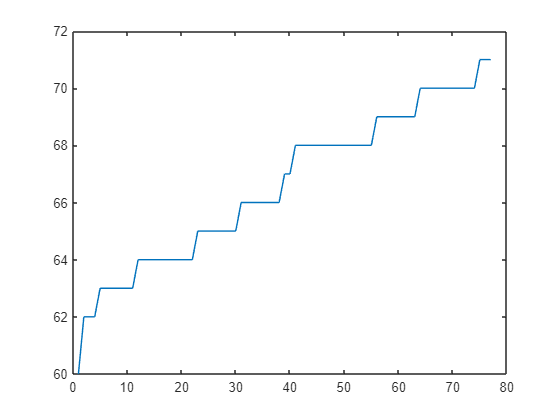

[T2,idx] = rmmissing(T);
plot(T2.Height)

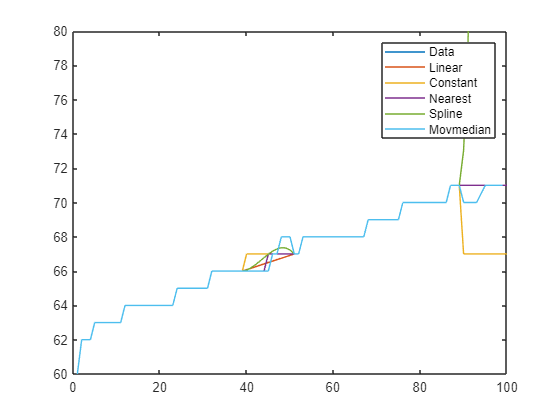



T.HeightLinear = fillmissing(T.Height,"linear");
T.HeightConstant = fillmissing(T.Height,"constant",67);
T.HeightNearest = fillmissing(T.Height,"nearest");
T.HeightSpline = fillmissing(T.Height,"spline");
T.HeightMovmedian = fillmissing(T.Height,"movmedian",20);

plot(x,T.Height,x,T.HeightLinear,x,T.HeightConstant,x,T.HeightNearest,x,T.HeightSpline,x,T.HeightMovmedian)
legend("Data","Linear","Constant","Nearest","Spline","Movmedian")

xlim([0 100])
ylim([60 80])

el objetivo de la gráfica es observar el comportamiento de cada método de interpolación y su comportamiento en la frontera, cuando solo existen valores en una dirección y solo faltantes en la otra.

Podemos agregar el parámetro "EndValues", por default el método es extrapolación, pero se puede cambiar por previous, next, nearest, none, scalar.

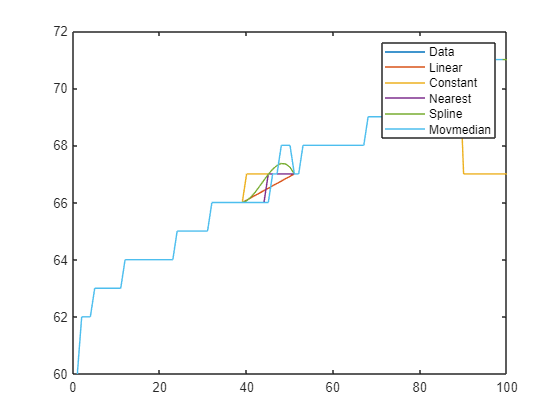

T.HeightLinear = fillmissing(T.Height,"linear");
T.HeightConstant = fillmissing(T.Height,"constant",67);
T.HeightNearest = fillmissing(T.Height,"nearest");
T.HeightSpline = fillmissing(T.Height,"spline","EndValues","nearest");
T.HeightMovmedian = fillmissing(T.Height,"movmedian",20);

plot(x,T.Height,x,T.HeightLinear,x,T.HeightConstant,x,T.HeightNearest,x,T.HeightSpline,x,T.HeightMovmedian)
legend("Data","Linear","Constant","Nearest","Spline","Movmedian")

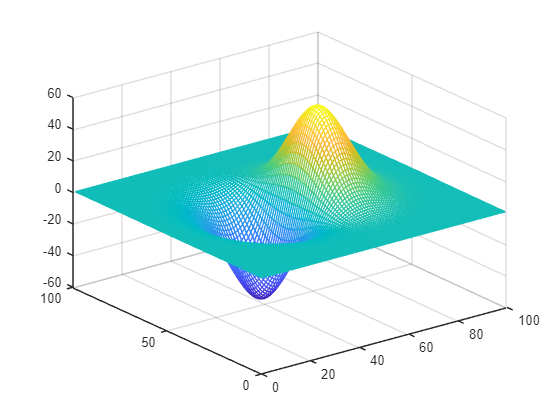

% Creamos campana gaussiana
h = fspecial('gaussian',100,12);
% Derivamos
h1=conv2(h,[-1 1],'same').*1000000;
mesh(h1)

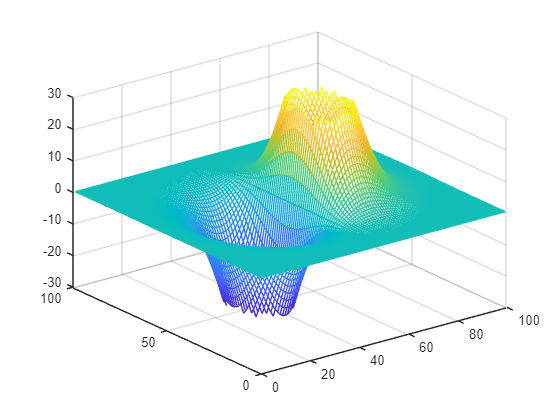

% punto maximo y minimo en 40,50 y 60,50
h2=h1;
h2(h1>30 | h1<-30)=nan;
mesh(h2)

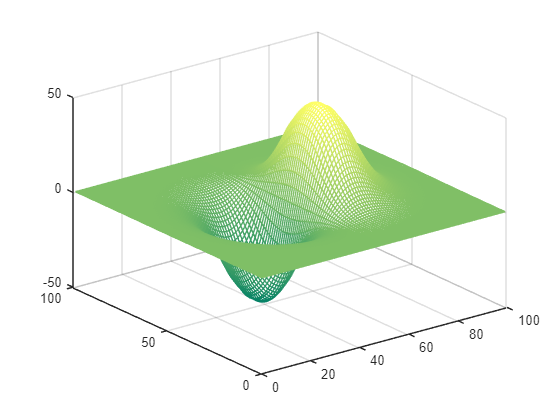

% interpolación o relleno de datos faltantesm puede hacerse con fillmissing
% o imresize en caso de datos que deseemos expandir o contraer en algun
% eje

method = "spline";
hspline = fillmissing(h2,method);
mesh(hspline)
colormap summer